# Question 2: Chebyshev Lpf

### Given Parameters

Sampling_Frequency = 2000;
Pass_Band_frequency  = 100;
Stop_band_frequency = 500;  
Pass_Band_attenuation = -1;    
Stop_Band_attenuation = -40;

### getting dicrete signal parameters

dp = 10^(Pass_Band_attenuation/20);
ds = 10^(Stop_Band_attenuation/20);
wp = 2*pi*Pass_Band_frequency/Sampling_Frequency;
ws = 2*pi*Stop_band_frequency/Sampling_Frequency;
Wp = tan(wp/2);
Ws = tan(ws/2);

## N,e,Ak,B

N = ceil(acosh(((1/(ds^2)-1)/(1/(dp^2)-1))^0.5)/acosh(Ws/Wp))

N = 3

e = (1/dp^2-1)^0.5

e = 0.5088

k = 0:2*N-1;
Ak = (2*k+1)*pi/(2*N);
B = 1/N*asinh(1/e);

### using cheb1ord

[N,wn] = cheb1ord(2*Pass_Band_frequency/Sampling_Frequency,2*Stop_band_frequency/Sampling_Frequency,-Pass_Band_attenuation,-Stop_Band_attenuation)

N = 3

wn = 0.1000

[a,b] = cheby1(N,-Pass_Band_attenuation,wn);

### plotting its response

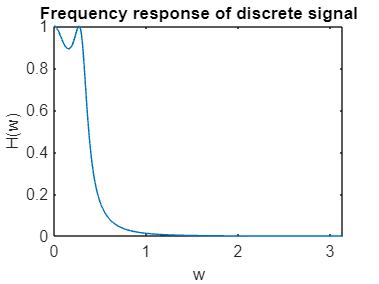

w = 0:0.01:pi;
Hw = freqz(a,b,w);
plot(w,abs(Hw))
title('Frequency response of discrete signal')
ylabel('H(w)')
xlabel('w')

### Checking using sine signals

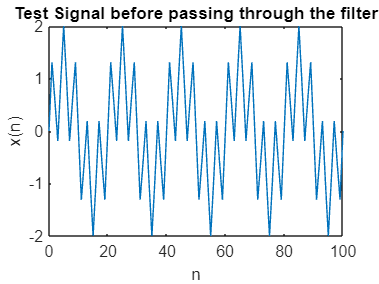

n = 0:100;
test_signal = sin(pi/10*n) + sin(pi/2*n);
plot(n,test_signal)
title('Test Signal before passing through the filter')
ylabel('x(n)')
xlabel('n')

### Passing through filter

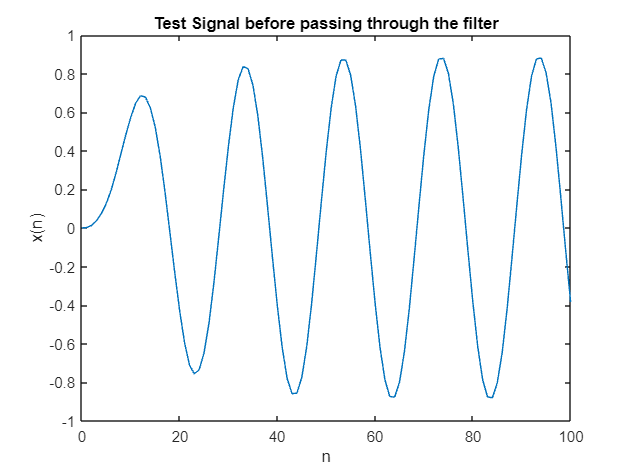

output = filter(a,b,test_signal);
plot(n,output)
title('Test Signal before passing through the filter')
ylabel('x(n)')
xlabel('n')